numSpinsPerDim = 30;
probSpinUp = 0.5;
J = 1;

% Temperatures to sample
numTemps = 20;
kTc = 2*J / log(1+sqrt(2)); % Curie temperature
kT = linspace(0, 2*kTc, numTemps);

% Preallocate to store results
Emean = zeros(size(kT));
Mmean = zeros(size(kT));
Cv    = zeros(size(kT));
Chi   = zeros(size(kT));
% Replace 'for' with 'parfor' to run in parallel with Parallel Computing Toolbox.
parfor_progress(numTemps);

  0%[>                                                  ]


parfor tempIndex = 1 : numTemps
    spin = initSpins(numSpinsPerDim, probSpinUp);
    spin = metropolis(spin, kT(tempIndex), J, 1e4 * numel(spin));
%     Emean(tempIndex) = energyIsing(spin, J);
%     Mmean(tempIndex) = magnetizationIsing(spin);
    [Emean(tempIndex), Mmean(tempIndex) ,Cv(tempIndex), Chi(tempIndex)] = StatisticProperties(spin,kT(tempIndex),J);
    parfor_progress;
end


100%[==================================================>]


parfor_progress(0);


100%[===================================================]


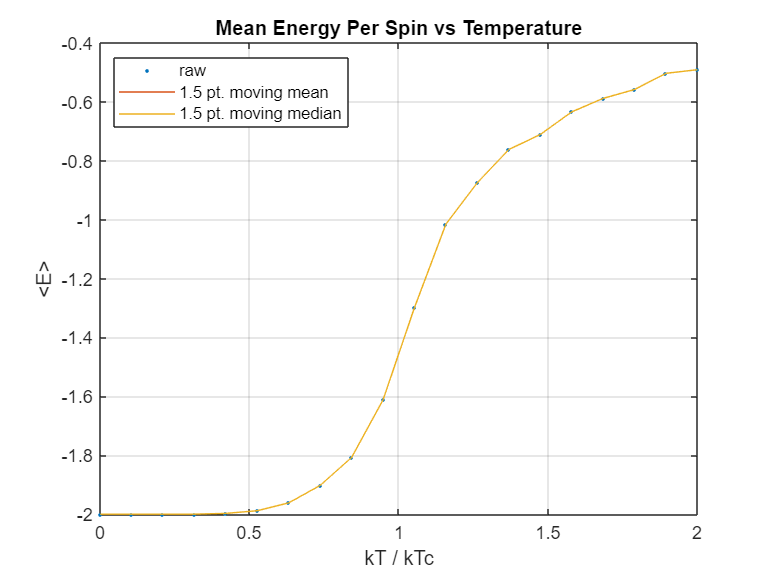

plot(kT / kTc, Emean, '.');

hold on;
window = (2^-3)*numTemps - 1;
plot(kT / kTc, movmean(  Emean, window));
plot(kT / kTc, movmedian(Emean, window));
hold off;

title('Mean Energy Per Spin vs Temperature');
xlabel('kT / kTc');
ylabel('<E>');
grid on;
legend('raw',...
    [num2str(window) ' pt. moving mean'],...
    [num2str(window) ' pt. moving median'],...
    'Location', 'NorthWest');

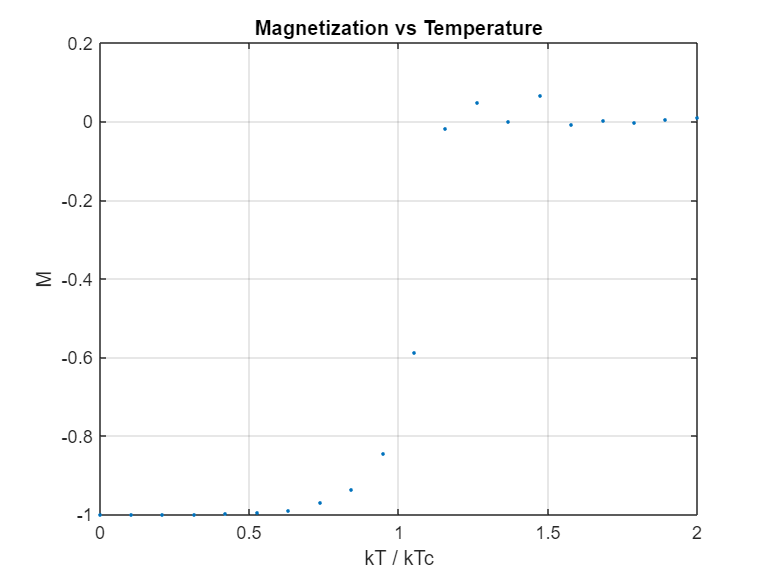


plot(kT / kTc, Mmean, '.');
grid on;
title('Magnetization vs Temperature');
xlabel('kT / kTc');
ylabel('M');

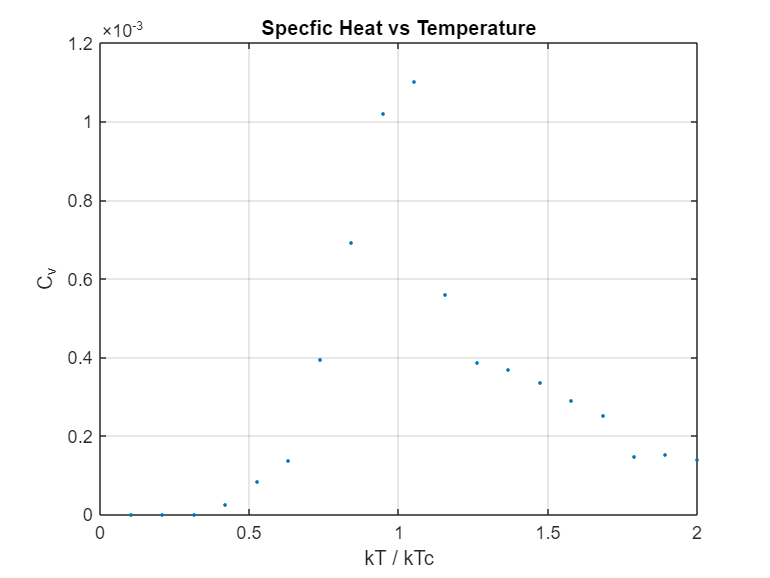


plot(kT / kTc, Cv, '.');
grid on;
title('Specfic Heat vs Temperature');
xlabel('kT / kTc');
ylabel('C_v');

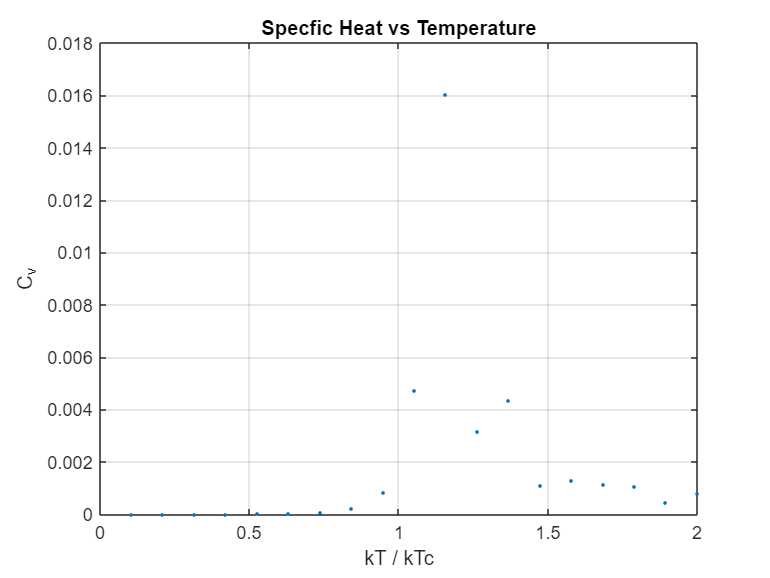


plot(kT / kTc, Chi, '.');
grid on;
title('Specfic Heat vs Temperature');
xlabel('k_BT / k_BT_c');
ylabel('\Chi');